## PRESENTAZIONE PROGETTO LEARNING-BASED CONTROL

### 1. INTRODUZIONE

Il progetto verte sulla risoluzione di uno problema di controllo classico nel campo del Reinforcement Learning: il **Mountain Car**, descritto nel libro *"Reinforcement Learning" di Richard S. Sutton e Andrew G. Barto*.

Come illustrato dagli autori, il **task **consiste nel guidare un'automobile sottodimensionata lungo una ripida strada di montagna a una dimensione. La difficoltà intrinseca del problema risiede nei vincoli fisici imposti: la forza di gravità è superiore alla forza massima che il motore dell'auto può applicare, di conseguenza l'agente non può raggiungere l'obiettivo (la cima della collina sulla destra) semplicemente accelerando in avanti.

L'agente quindi si trova ad affrontare il seguente problema di controllo: deve apprendere come guidare l'auto lontano dall'obiettivo, cioè risalendo la pendenza opposta a sinistra, per accumulare sufficiente energia per superare la pendenza e raggiungere la meta.

### 2. FORMULAZIONE DEL PROBLEMA

In accordo con la formulazione standard di Sutton & Barto, avremo che:

**2a) ****SPAZIO DI STATO E AZIONI**

l sistema è descritto da due variabili di stato continue e da un set di azioni discrete.

**Spazio di Stato (S)**: lo stato all'istante di tempo $k$ è un vettore bidimensionale:


$$x_k =\left\lbrack \begin{array}{c}
p_k \\
v_k 
\end{array}\right\rbrack$$


dove:

- $p_k$ rappresenta la **posizione** dell'auto lungo l'asse orizzontale `--> `variabile vincolata t.c. $p_k \in \left\lbrack -1\ldotp 2,0\ldotp 5\right\rbrack$

- $v_k$ rappresenta la **velocità** dell'auto `-->` variabile vincolata t.c. $v_k \in \left\lbrack -0\ldotp 07,0\ldotp 07\right\rbrack$

**Spazio delle Azioni (A)**: ad ogni passo temporale $k$, l'agente sceglie un'azione $u_k$ dall'insieme discreto:

- $u_k =-1$`--> `spinta massima a sinistra (retromarcia)

- $u_k =0$ `-->` nessuna spinta (folle)

- $u_k =+1$`--> `spinta massima a destra (avanti)

**2b) ****DINAMICA DEL SISTEMA**

La fisica del sistema è semplificata. La dinamica a tempo discreto è governata dalle seguenti equazioni di stato:


$$\left\lbrace \begin{array}{ll}
v_{k+1} =v_k +\left(0\ldotp 001\right)\;u_k -\left(0\ldotp 0025\right)\;\cos \left(3p_k \right) & \textrm{con}-0\ldotp 07\le v_k \le +0\ldotp 07\\
p_{k+1} =p_k +v_{k+1}  & \textrm{con}-1\ldotp 2\le p_k \le 0\ldotp 5
\end{array}\right.$$


OSS.

- il termine $\left(0\ldotp 001\right)\;u_k$ rappresenta la *forza del motore dell'auto*

- il termine $-\left(0\ldotp 0025\right)\;\cos \left(3p_k \right)$ rappresenta l'*effetto della gravità* che dipende dalla pendenza della collina ($\cos \left(3p_k \right)$)

- la nuova posizione invece, viene calcolata utilizzando la nuova velocità $v_{k+1}$, non quella vecchia

NOTA

- Se $p_{k+1} \ge 0\ldotp 5$ l'episodio termina con successo

- Se, invece, l'auto raggiunge il limite sinistro $p_{k+1} \le -1\ldotp 2$ avremo che:

                         -    la posizione viene reimpostata a $p_k =1\ldotp 2$

                         -    la velocità viene azzerata $v_{k+1} =0$

**2c) ****REWARD**

Il problema è formulato come un compito di minimizzazione del tempo:

- $R_k =-1$ `-->` per ogni passo temporale $k$ in cui l'obiettivo non è raggiunto

- $R_k =0$ `-->` quando l'obiettivo viene raggiunto

L'obiettivo è minimizzare la reward, cioè avere il numero minimo di passi per raggiungere la cima

**2d) ****CONDIZIONI INIZIALI**

Vengono considerate le seguenti due zone principali per il problema:

- Valle: si trova circa a $p=-0\ldotp 5$

- Cima: si trova a $p=0\ldotp 5$

Se facessimo partire l'auto sempre dallo stesso identico punto (ad esempio sempre da $p_0 =-0\ldotp 5$, l'agente imparerebbe a memoria una sequenza di azioni, che poi però non funzionerebbe anche se spostassimo l'auto di un solo millimetro. 

Pertanto, gli autori suggeriscono di far partire l'auto in una posizione casuale compres tra -0.6 e -0.4:

- questo intervallo rappresenta la "zona centrale" della valle

- la velocità iniziale è sempre 0 (auto ferma)

Pertanto viene introdotta incertezza nella posizione di partenza (fondo valle casuale) per costringere l'agente a generalizzare la strategia di controllo e non memorizzare una traiettoria fissa

### 3. STRATEGIA DI RISOLUZIONE

Sebbene Sutton & Barto utilizzino il Mountain Car per introdurre metodi di apprendimento basati su *Function Approximation* a causa della natura continua dello spazio degli stati, in questo progetto abbiamo adottato un approccio comparativo:

- **Q-Learning Tabular: **inizialmente abbiamo affrontato il problema discretizzando lo spazio degli stati continuo, questo ci ha permesso di applicare l'algoritmo Q-Learning nella sua forma tabellare.

                        *Obiettivo*: ci permette di comprendere l'aggiornamento dell'action-value function reale $Q\left(x,u\right)$ e visualizzarla in maniera esplicita senza l'approssimazione introdotta dalla function approximation, quindi ci permette di osservare come l'agente apprende.

- **Linear Function Approximation (RBF):** successivamente, implementaremo una soluzione basata su ***Radial Basis Function ***e in tal caso, l'agente invece di memorizzare ogni coppia stato-azione in una tabella, utilizzerà un vettore di pesi per approssimare l'action-value function ${\hat{Q} }_{\theta \;} \left(x,u\right)$

                         *Obiettivo: *dimostrare che l'utilizzo di function approximators permette una migliore generalizzazione tra gli stati vicini e una gestione più efficiente dello spazio continuo, superando i limiti imposti dal metodo tabellare

clear
clc
close all

% PARAMETRI DEL SISTEMA

% definiamo le azioni possibili:
%   --> -1 (retromarcia)
%   -->  0 (folle)
%   --> +1 (avanti)
par.actions = [-1, 0, 1];
par.n_actions = length(par.actions);

% limiti imposti dagli autori:
%   --> -1.20 <= posizione <= 0.50 (0SS. pos >= 0.5 è il nostro obiettivo)
%   --> -0.07 <= velocità  <= 0.07
pos_min = -1.2;
pos_max = 0.5;
vel_min = -0.07;
vel_max = 0.07;

% parametri per il Reinforcement Learning
alpha = 0.05;            % Learning Rate
gamma = 0.995;           % Discount Factor
epsilon_start = 1.0;     % Partiamo da una massima esplorazione
num_episodes = 30000;    % Abbiamo bisogno di meno episodi rispetto al Cart-and-Pole
max_steps = 1000;        % Numero massimo di step all'interno di un episode

% decadimento della Epsilon
epsilon_min = 0.01;
epsilon_decay = (epsilon_min / epsilon_start)^(1 / (num_episodes * 0.80));

% DISCRETIZZIAMO LO SPAZIO DELLO STATO
n_intervalli_pos = 40; % numero intervalli posizione 
n_intervalli_vel = 40; % numero intervalli velocità

% andiamo a creare i vari intervalli
dis_pos = linspace(pos_min, pos_max, n_intervalli_pos+1);
dis_vel = linspace(vel_min, vel_max, n_intervalli_vel+1);

% inizializzazione Q_Table: [Posizione, Velocità, Azione]
Q_table = zeros(n_intervalli_pos, n_intervalli_vel, par.n_actions);

% Q-LEARNING ALGORITHM

% buffer per salvare le reward
rewards_per_episode = zeros(num_episodes, 1);
eps = epsilon_start;

for ep = 1:num_episodes

    % definiamo lo stato iniziale, quindi otteniamo gli indici discreti rispettivi
    x_0 = stato_iniziale();
    [idx_pos, idx_vel] = discretizzazione(x_0, dis_pos, dis_vel);

    % reward iniziale
    reward = 0;

    % per ogni step dell'episode ripetiamo i seguenti passaggi
    for step = 1:max_steps
        
        % 1. selezioniamo un'azione u_k attraverso eps-greedy policy
        if rand < eps
           action_idx = randi(par.n_actions); % selezioniamo un'azione casuale con probabilità Epsilon (EXPLORE)
        else
           [~, action_idx] = max(Q_table(idx_pos, idx_vel, :), [], 3); % selezioniamo la greedy action con probabilità (1-Epsilon) (EXPLOIT) 
        end

        % 2. eseguiamo u_k, quindi osserviamo x_(k+1) e r_(k+1)
        [x_k_1, r_k_1, cima_raggiunta] = simulatore(x_0, action_idx, par);  % simulatore dinamica del sistema
        [idx_p_k_1, idx_v_k_1] = discretizzazione(x_k_1, dis_pos, dis_vel); % discretizziamo il nuovo stato
        
        % 3. aggiornamento della action-value function Q(x,u)
        if cima_raggiunta == true
           % se raggiungiamo la cima l'episodio è terminato non avremo uno stato futuro (x_k_1), quindi gamma * max(Q_table(idx_p_k_1, idx_v_k_1, :)) = 0
           Q_table(idx_pos, idx_vel, action_idx) = Q_table(idx_pos, idx_vel, action_idx) + alpha * (r_k_1 - Q_table(idx_pos, idx_vel, action_idx)); 
           
        else
           Q_table(idx_pos, idx_vel, action_idx) = Q_table(idx_pos, idx_vel, action_idx) + alpha * (r_k_1 + gamma * max(Q_table(idx_p_k_1, idx_v_k_1, :)) - Q_table(idx_pos, idx_vel, action_idx)); 
        end

        reward = reward + r_k_1;

        % 4. aggiorniamo lo stato
        x_0 = x_k_1;
        idx_pos = idx_p_k_1;
        idx_vel = idx_v_k_1;

        % se abbiamo raggiunto la cima ci fermiamo ed eseguiamo un altro episode, mentre se non l'abbiamo raggiunta proseguiamo con l'iterazione degli step
        if cima_raggiunta == true
            break;
        end
    end

    % decadimento della epsilon
    eps = eps * epsilon_decay;
    rewards_per_episode(ep) = reward;

    if mod(ep,500) == 0
        fprintf('Ep: %d | Reward: %.1f | Eps: %.3f\n', ep, mean(rewards_per_episode((ep-99):ep)), eps);
    end
end

Ep: 500 | Reward: -993.0 | Eps: 0.909
Ep: 1000 | Reward: -849.0 | Eps: 0.825
Ep: 1500 | Reward: -661.4 | Eps: 0.750
Ep: 2000 | Reward: -468.2 | Eps: 0.681
Ep: 2500 | Reward: -388.3 | Eps: 0.619
Ep: 3000 | Reward: -339.8 | Eps: 0.562
Ep: 3500 | Reward: -296.3 | Eps: 0.511
Ep: 4000 | Reward: -272.3 | Eps: 0.464
Ep: 4500 | Reward: -263.7 | Eps: 0.422
Ep: 5000 | Reward: -234.2 | Eps: 0.383
Ep: 5500 | Reward: -230.4 | Eps: 0.348
Ep: 6000 | Reward: -215.2 | Eps: 0.316
Ep: 6500 | Reward: -192.8 | Eps: 0.287
Ep: 7000 | Reward: -195.2 | Eps: 0.261
Ep: 7500 | Reward: -199.3 | Eps: 0.237
Ep: 8000 | Reward: -178.1 | Eps: 0.215
Ep: 8500 | Reward: -177.6 | Eps: 0.196
Ep: 9000 | Reward: -174.3 | Eps: 0.178
Ep: 9500 | Reward: -179.1 | Eps: 0.162
Ep: 10000 | Reward: -171.2 | Eps: 0.147
Ep: 10500 | Reward: -157.7 | Eps: 0.133
Ep: 11000 | Reward: -169.0 | Eps: 0.121
Ep: 11500 | Reward: -157.1 | Eps: 0.110
Ep: 12000 | Reward: -159.4 | Eps: 0.100
Ep: 12500 | Reward: -139.2 | Eps: 0.091
Ep: 13000 | Reward: 

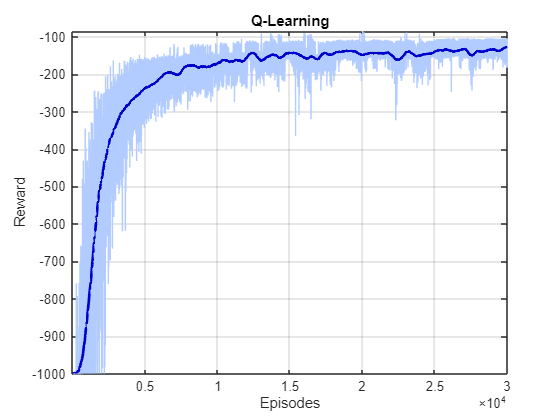

% GRAFICI Q-LEARNING
figure;

% plot of raw data (light blue)
plot(rewards_per_episode, 'Color', [0.7, 0.8, 1.0], 'HandleVisibility', 'off'); 
hold on;

% calculation and plot of the moving average (dark blue)
moving_avg = movmean(rewards_per_episode, 500); % Average over 500 episodes to clean up the graph
plot(moving_avg, 'Color', [0, 0, 0.8], 'LineWidth', 2, 'DisplayName', 'Trend (Media Mobile)');

title('Q-Learning');
xlabel('Episodes');
ylabel('Reward');
grid on;
axis tight;

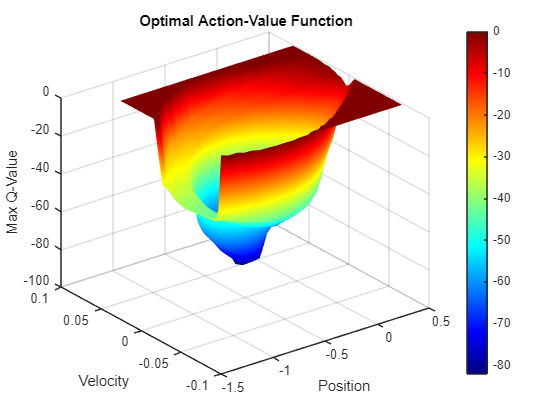

% VISUALIZZAZIONE ACTION-VALUE FUNCTION OTTIMALE 
figure('Color', 'w');

% calcoliamo Q(x,u) = max_u{Q(x,u)}
Q_table_opt = max(Q_table, [], 3);

% creiamo la griglia per il grafico
centri_p = (dis_pos(1:end-1) + dis_pos(2:end)) / 2;
centri_v = (dis_vel(1:end-1) + dis_vel(2:end)) / 2;
[P, V] = meshgrid(centri_p, centri_v);

% disegniamo la superficie
surf(P, V, Q_table_opt');

% miglioriamo l'estetica e la leggibilità
shading interp; % rimuove le linee nere, rende i colori sfumati
colormap jet;   % usa colori forti (Rosso = ALto, Blu = Basso)
colorbar;

xlabel('Position'); 
ylabel('Velocity');
zlabel('Max Q-Value');
title('Optimal Action-Value Function');

OSS.

Questo grafico rappresenta il 'cervello' del nostro agente. Ci mostra quanto sia buono un determinato stato, in relazione al raggiungimento dell'obiettivo finale: minimizzare il tempo di salita verso la collina di destra. Siccome ogni passo costa -1, l'asse verticale (z) ci dice: *"Quanti passi mancano alla vittoria?" *

Cosa possiamo notare dal grafico:

- Il Fondo Valle (la zona blu): il punto blu scuro è al centro (coordinate -0.5, 0). Qui l'auto è ferma nel punto più basso della valle, ed è lo stato peggiore perchè l'auto non ha nè altezza (energia potenziale) nè velocità (energia cinetica). Avremo il valore più basso perchè l'agente deve spendere molto tempo per guadagnare spinta

- Muro Sinistro: possiamo notare come in posizione -1.2 la superficie cambia bruscamente. In qeusto caso l'agente ha imparato che andare al di là del limite sinistro, azzera la velocità.

% TEST SUL Q-LEARNING
max_step_test = 1000;
stati_tot = [];

% inizializzazione
x_0 = stato_iniziale();
stati_tot = [stati_tot, x_0];
[idx_pos, idx_vel] = discretizzazione(x_0, dis_pos, dis_vel);

for step= 1:max_step_test

    % 1. Selezioniamo l'azione migliore (greedy) dalle Q-table addestrata
    [~, action_idx] = max(Q_table(idx_pos, idx_vel, :), [], 3);

    % 2. Simulazione dinamica
    [x_k_1, r_k_1, cima_raggiunta] = simulatore(x_0, action_idx, par);
    
    % Salviamo lo stato per l'animazione
    stati_tot = [stati_tot, x_k_1];
    
     if cima_raggiunta == true
       fprintf('Cima raggiunta in %d passi!\n', step);
       break;
     end

    % 3. Aggiornamento indici
    [idx_pos, idx_vel] = discretizzazione(x_k_1, dis_pos, dis_vel);
    x_0 = x_k_1;
end

Cima raggiunta in 152 passi!


Generazione video in corso...
Video salvato come: animation_Mountain_Car


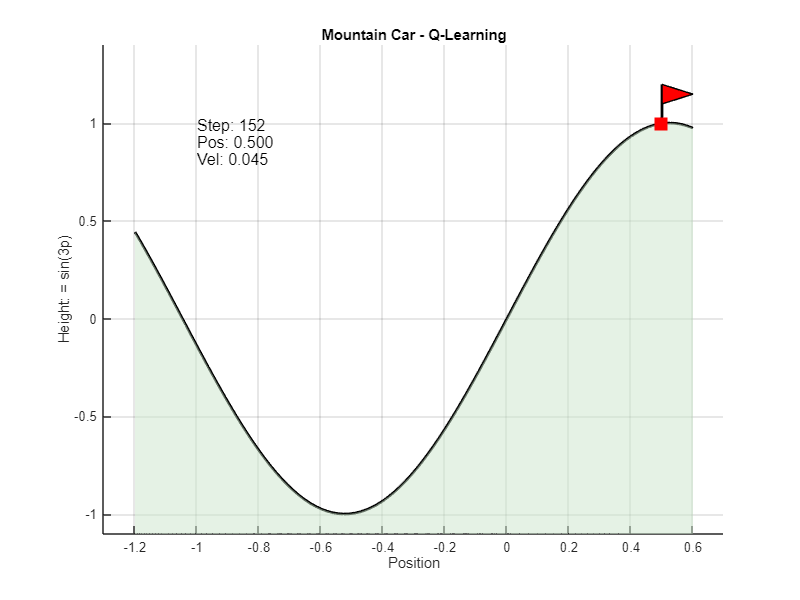

% animazione
animazione_test(stati_tot, 'animation_Mountain_Car');

% Q-Learning con LINEAR APPROXIMATION (RBF)

% Parametri Learning
alpha_RBF = 0.01;             % Learning Rate (più alto del tabellare perchè le RBF sono normalizzate)
gamma_RBF = 0.995;            % Discount Factor
num_episodes_RBF = 10000;     % Bastano meno episodi rispetto al tabellare
max_steps_RBF = 500;          % Max step per episodio

% Gestione Epsilon
epsilon_start_RBF = 1.0;
epsilon_min_RBF = 0.01;
epsilon_decay_RBF = (epsilon_min_RBF / epsilon_start_RBF)^(1 / (num_episodes_RBF * 0.7));

% Vogliamo coprire lo spazio 2D (Posizione, Velocità) con delle Gaussiane --> scegliamo una griglia di centri
n_centri_pos = 10;
n_centri_vel = 10;

c_pos = linspace(pos_min, pos_max, n_centri_pos);
c_vel = linspace(vel_min, vel_max, n_centri_vel);

% meshgrid() --> ci permette di generare tutte le possibili combinazioni di coordinate (x,y) 
%                partendo da due vettori. Verranno, quindi, create due matrici: C_POS e C_VEL
[C_POS, C_VEL] = meshgrid(c_pos, c_vel);

% (:) --> ci permette di trasformare le matrici in un'unica colonna, quindi le mettiamo vicine
%         e otteniamo una matrice C dove ogni riga è un centro (p_c, v_c)
C = [C_POS(:), C_VEL(:)];
N = size(C, 1);

% Calcoliamo le larghezze (sigma) per ogni dimensione
sigma = zeros(1, 2);
sigma(1) = (c_pos(2) - c_pos(1)); % Larghezza per la posizione 
sigma(2) = (c_vel(2) - c_vel(1)); % Larghezza per la velocità

% inizializzazione dei pesi Theta [N, N_azioni]
Theta = zeros(N, par.n_actions);
rewards_per_episode_RBF = zeros(num_episodes_RBF, 1);
eps_RBF = epsilon_start_RBF;

% Q-Learning con Function Approximation
for ep = 1:num_episodes_RBF
    
    x_0 = stato_iniziale();
    phi = get_phi(x_0, C, sigma);
    
    total_reward = 0;
    
    for step = 1:max_steps_RBF
        
        % 1. Selezione azione (Epsilon-Greedy)
        if rand < eps_RBF
            action_idx = randi(par.n_actions);
        else
            [~, action_idx] = max(phi' * Theta);
        end
        
        % 2. Osserviamo r_k_1 e x_k_1
        [x_k_1, r_k_1, cima_raggiunta] = simulatore(x_0, action_idx, par);
        total_reward = total_reward + r_k_1;
        
        % 3. Q(x_k, u_k)
        Q_k = phi' * Theta(:, action_idx);
        
        if cima_raggiunta == true
            % 4a. Q(x_k_1, u_k_1) = 0
            % OSS. --> without gamma*max(Q_k_1) since we are in a terminal state 
            %          the estimated future value will be zero
            target = r_k_1;
        else
            % 4b. Q(x_k_1, u_k_1)
            phi_next = get_phi(x_k_1, C, sigma);
            Q_k_1 = phi_next' * Theta;
            target = r_k_1 + gamma_RBF * max(Q_k_1);
        end
        
        % 5. Weight Update: we update ONLY the selected action_idx column
        Theta(:, action_idx) = Theta(:, action_idx) + alpha_RBF * (target - Q_k) * phi;
        
        if cima_raggiunta == true
            break;
        end
        
        % 6. Update
        x_0 = x_k_1;
        phi = phi_next;
    end
    
    % Updates at end of episodes
    rewards_per_episode_RBF(ep) = total_reward;
    eps_RBF = eps_RBF * epsilon_decay_RBF;
    
    if mod(ep, 200) == 0
        fprintf('Ep: %d | Reward: %.1f | Eps: %.3f\n', ...
            ep, mean(rewards_per_episode_RBF(ep-99:ep)), eps_RBF);
    end
end

Ep: 200 | Reward: -500.0 | Eps: 0.877
Ep: 400 | Reward: -462.6 | Eps: 0.769
Ep: 600 | Reward: -377.1 | Eps: 0.674
Ep: 800 | Reward: -294.5 | Eps: 0.591
Ep: 1000 | Reward: -262.4 | Eps: 0.518
Ep: 1200 | Reward: -236.2 | Eps: 0.454
Ep: 1400 | Reward: -204.9 | Eps: 0.398
Ep: 1600 | Reward: -185.0 | Eps: 0.349
Ep: 1800 | Reward: -170.1 | Eps: 0.306
Ep: 2000 | Reward: -168.4 | Eps: 0.268
Ep: 2200 | Reward: -153.1 | Eps: 0.235
Ep: 2400 | Reward: -150.0 | Eps: 0.206
Ep: 2600 | Reward: -136.7 | Eps: 0.181
Ep: 2800 | Reward: -139.1 | Eps: 0.158
Ep: 3000 | Reward: -136.9 | Eps: 0.139
Ep: 3200 | Reward: -125.3 | Eps: 0.122
Ep: 3400 | Reward: -135.5 | Eps: 0.107
Ep: 3600 | Reward: -123.3 | Eps: 0.094
Ep: 3800 | Reward: -128.3 | Eps: 0.082
Ep: 4000 | Reward: -135.9 | Eps: 0.072
Ep: 4200 | Reward: -128.9 | Eps: 0.063
Ep: 4400 | Reward: -143.7 | Eps: 0.055
Ep: 4600 | Reward: -148.3 | Eps: 0.048
Ep: 4800 | Reward: -137.4 | Eps: 0.043
Ep: 5000 | Reward: -148.7 | Eps: 0.037
Ep: 5200 | Reward: -142.1 | E

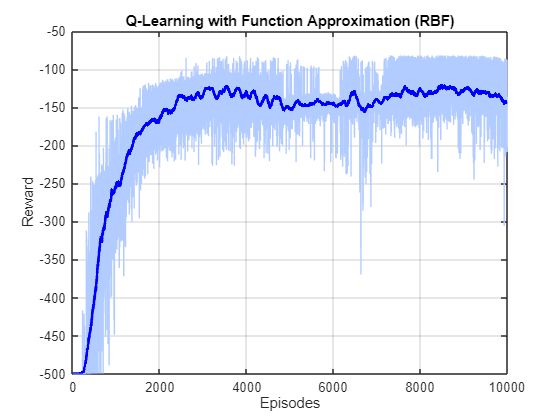

% Grafico --> Q-Learning con Linear Function Approximation
figure;

% plot of raw data (light blue)
plot(rewards_per_episode_RBF, 'Color', [0.7, 0.8, 1.0]); 
hold on;

% calculation and plot of the moving average (dark blue)
plot(movmean(rewards_per_episode_RBF, 100), 'b', 'LineWidth', 2);

title('Q-Learning with Function Approximation (RBF)');
xlabel('Episodes'); ylabel('Reward');
grid on;

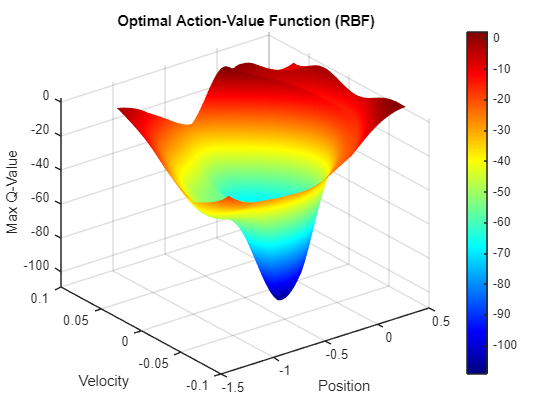

% VISUALIZZAZIONE ACTION-VALUE FUNCTION OTTIMALE (RBF)
figure('Color', 'w')

% creiamo una griglia per la visualizzazione
% OSS. --> a differenza del tabular che era limitato a 40x40, in questo caso 
%          possiamo scegliere una risoluzione alta per mostrare quanto è liscia la funzione
n_griglia = 60;
centri_pos = linspace(pos_min, pos_max, n_griglia);
centri_vel = linspace(vel_min, vel_max, n_griglia);

[P, V] = meshgrid(centri_pos, centri_vel);

% ricostruiamo la superficie Z punto per punto
Q = zeros(n_griglia, n_griglia);

for i = 1:n_griglia
    for j = 1:n_griglia
        
        % singolo stato della griglia
        x_eval = [P(i,j); V(i,j)];
        
        % calcoliamo phi per tale stato
        % OSS. --> usiamo gli stessi C e sigma dell'addestramento
        phi_BIS = get_phi(x_eval, C, sigma);
        
        % Estraiamo il valore massimo (Greedy)
        Q(i,j) = max(phi_BIS' * Theta);
    end
end

% disegniamo la superficie
surf(P, V, Q');

% miglioriamo l'estetica e la leggibilità
shading interp; % rimuove le linee nere, rende i colori sfumati
colormap jet;   % usa colori forti (Rosso = ALto, Blu = Basso)
colorbar;

xlabel('Position'); 
ylabel('Velocity');
zlabel('Max Q-Value');
title('Optimal Action-Value Function (RBF)');

% TEST Q-LEARNING CON RBF
max_step_test_RBF = 500;
stati_tot_RBF = [];

% inizializzazione
x_0_RBF = stato_iniziale();
stati_tot_RBF = [stati_tot_RBF, x_0_RBF];

for step = 1:max_step_test_RBF
    % selezioniamo azione GREEDY
    [~, action_idx_RBF] = max(phi' * Theta);

    % simulazione dinamica --> osserviamo r_k_1 e x_k_1
    [x_k_1_RBF, r_k_1_RBF, cima_raggiunta] = simulatore(x_0_RBF, action_idx_RBF, par);
    
    % Salviamo lo stato per l'animazione
    stati_tot_RBF = [stati_tot_RBF, x_k_1_RBF];

    if cima_raggiunta == true
       fprintf('Cima raggiunta in %d passi!\n', step);
       break;
    end

    % Aggiornamento
    x_0_RBF = x_k_1_RBF;
    phi = get_phi(x_0_RBF, C, sigma);
end

Cima raggiunta in 98 passi!


Generazione video in corso...
Video salvato come: animation_Mountain_Car_RBF


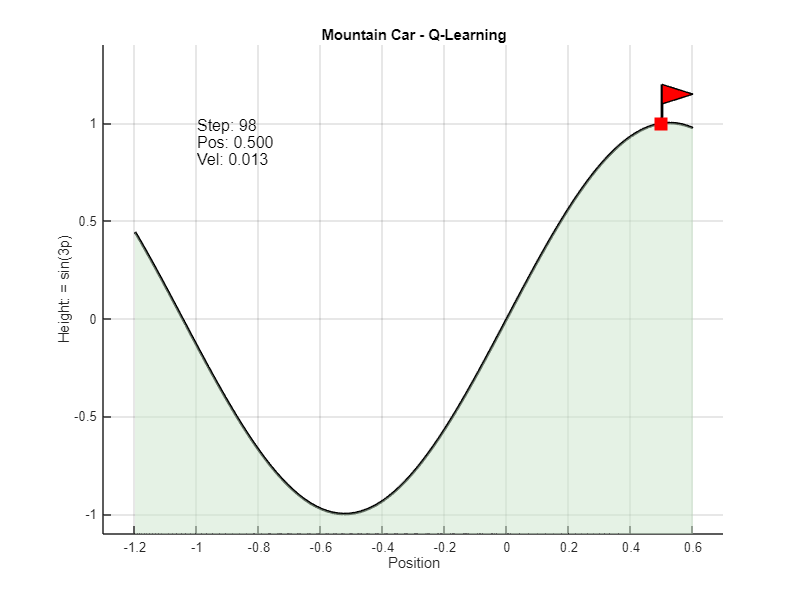

% animazione
animazione_test(stati_tot_RBF, 'animation_Mountain_Car_RBF');

**OSSERVAZIONI FINALI**

Andando ad analizzare il comportamento del nostro agente nei due casi: Q-Learning Tabular e Q-Learning con FUnction Approximation, notiamo delle differenze evidenti:

**1) La Fluidità della Soluzione**

- Tabular: la Action-Value Function (visualizzazione 3D) appare "a gradini". Questo è dovuto al fatto che ogni cella della grigli 40 x 40 è indipendente.

- RBF: La soluzione sarà una superficie liscia e continua. Grazie alle gaussiane, l'agente impare una funzione matematica. Se impara qualcosa in un punto, tale conoscenza si "spalma" sui punti vicini.

**2) Efficienza dei Parametri**

- Tabular: Abbiamo una griglia 40 x 40, quindi `--> `40 x 40 x 3 (azioni) = 4800 valori

- RBF: Abbiamo una griglia 10 x 10, quindi `-->` 10 x 10 x 3 (azioni) = 300 valori

     RBF riesce ad ottenre risultati comparabili (o addirittura migliori) usando 16 volte meno memoria. Questo ci dimostra la potenza della Function Approximation nel combattere la "Curse of Dimensionality"

**3) Velocità di Apprendimento**

- Guardando i grafici oppure i dati, notiamo che la RBF converge un po' prima o in modo più stabile nelle fasi iniziali

- Questo è dovuto al fatto che nel tabular, l'agente deve visitare fisicamente ogni quadratino della griglia per imparare. Nella RBF, grazie alla *generalizzazione*, se sono presenti buone stime dei valori di Q di determinati stati, l'agente può prendere decisioni di controllo ragionevoli negli stati vicini.

**OSS.**

Funzioni Locali utilizzate nel codice di cui sopra


% % 1. simulatore() --> ci consente di simulare la dinamica del sistema presentato da Sutton & Barto, 
%                       quindi ci fornirà lo stato successivo in cui si troverà il nostro agente, la reward ottenuta e 
%                       se abbiamo raggiunto o meno la cima, cioè se abbiamo terminato l'obiettivo.
%                       Passeremo alla funzione i seguenti parametri:
%                           - x, cioè il vettore di stato (x(1) = posizione, x(2) = velocità)
%                           - act_idx, cioè l'indice dell'azione
%                           - par, una struct contenente dei parametri utili
function [x_k_1, reward, cima_raggiunta] = simulatore(x, act_idx, par)
         
         % definiamo le nostre VARIABILI DI STATO, quindi il nostro INPUT DI CONTROLLO
         p = x(1);
         v = x(2);
         u = par.actions(act_idx);

         % DINAMICA DEL SISTEMA (da Sutton & Barto)
         v_k_1 = v + 0.001 * u - 0.0025 * cos(3*p);

         % facciamo rispettare i LIMITI DI VELOCITA':
         if v_k_1 > 0.07
            v_k_1 = 0.07;
         elseif v_k_1 < -0.07
            v_k_1 = -0.07;
         end

         p_k_1 = p + v_k_1;

         % facciamo rispettare i LIMITI DI POSIZIONE:
         if p_k_1 < -1.2
            % se andiamo fuori dal limite sinistro --> azzeriamo la velocità
            p_k_1 = -1.2;
            v_k_1 = 0; 
         elseif p_k_1 > 0.5
             p_k_1 = 0.5;
         end

         x_k_1 = [p_k_1 ; v_k_1];

         % REWARD e TERMINAL CONDITIONS
         % OSS. --> L'obiettivo è avere il valore di reward il più alto possibile, 
         %          quindi minimizzare il tempo che impiega l'auto a salire verso la montagna.
         if p_k_1 >= 0.5
            cima_raggiunta = true;
            reward = 0;
         else
            cima_raggiunta = false;
            reward = -1;
         end
end

% % 2. discretizzazione() --> ci consente di attribuire alla nostra varibile di stato "continua" un valore "discreto", 
%                             che corrisponde ad un intervallo tra quelli in cui è stata divisa la variabile.
%                             Passeremo alla funzione i parametri:
%                               - x, vettore dello stato [2x1]
%                               - int_p, intervalli in cui è stata divisa la variabile posizione
%                               - int_v, intervalli in cui è stata divisa la variabile velocità
function [idx_p, idx_v] = discretizzazione(x, int_p, int_v)
            
         % funzione di MATLAB discretize() --> restituisce gli indici a cui corrisponde la variabile continua, 
         %                                     in base agli intervalli in
         %                                     cui è stata divisa.
         % Come funziona l'assegnazione di discretize()?
         % Facciamo l'esempio con la variabile posizione, quindi x(1). La variabile di stato ha un valore continuo, 
         % pertanto discretize() assegnerà tale variabile all'intervallo corrispondente seguendo tale principio:
         % intervallo(j) <= x(1) < intervallo(j+1) con 1 <= j < n_intervalli_pos
         idx_p = discretize(x(1), int_p);
         idx_v = discretize(x(2), int_v);

         % siccome discretize() ci restituirà NaN (Not a Number) se il valore continuo è fuori dal range (anche solo di una cifra decimale "infinitesima"),  
         % presentiamo le seguenti condizioni if per proteggerci da eventuali errori
         if isnan(idx_p)
            if x(1) <= int_p(1)
               idx_p = 1;                   % se è uscito a sinistra --> primo intervallo
            else
               idx_p = length(int_p) - 1;   % se è uscito a destra   --> ultimo intervallo
            end
         end
         
         if isnan(idx_v)
             if x(2) <= int_v(1)
                idx_v = 1;                  % se la velocità è troppo negativa --> primo intervallo
             else
                idx_v = length(int_v)-1;    % se la velocità è troppo positiva --> ultimo intervallo
             end
         end

end

% % 3. stato_iniziale() --> ci restituisce lo stato iniziale, cioè un valore casuale della posizione 
%                           compreso tra -0.6 e -0.4, come descritto dagli autori (Sutton & Barto)
function x0 = stato_iniziale()
         
         % posizione casuale nel fondo valle [-0.6, -0.4]
         p = -0.6 + (0.2 * rand());
         v = 0; % velocità iniziale settata a zero
         x0 = [p;v];
end

% % 4. animazione_test() --> ci permette di descrivere l'animazione del sistema Mountain Car, quindi di avere un supporto visivo ulteriore 
%                            oltre ai grafici e alla rappresentazione 3D dell'Action-Value Function.
%                            Passeremo alla funzione i parametri:
%                               - stati, vettore che contiene tutti gli stati [2 x max_steps]
%                               - video_filename, nome con cui abbiamo salvato il file video
function animazione_test(stati, video_filename)
         
         % Creazione della figura
         h_fig = figure('Name', 'Animazione Mountain Car', 'Color', 'w');
         set(h_fig, 'Position', [100, 100, 800, 600]);
         clf; hold on; grid on;

         % Disegniamo la MONTAGNA
         % OSS. --> la funzione montagna è definita come sin(3*p)
         p_range = linspace(-1.2, 0.6, 100); 
         h_montagna = sin(3 * p_range);

         % Plot della linea della montagna
         plot(p_range, h_montagna, 'k', 'LineWidth', 2);
    
         % Riempimento colore sotto la montagna
         fill([p_range, fliplr(p_range)], [h_montagna, -2*ones(size(h_montagna))], [0.8, 0.9, 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.5);

         % disegniamo la BANDIERINA del traguardo a pos = 0.5
         plot([0.5, 0.5], [sin(3*0.5), sin(3*0.5)+0.2], 'k-', 'LineWidth', 2); % asta
         patch([0.5, 0.5, 0.6], [sin(3*0.5)+0.2, sin(3*0.5)+0.1, sin(3*0.5)+0.15], 'r'); % bandiera
    
         xlim([-1.3, 0.7]);
         ylim([-1.1, 1.4]);
         xlabel('Position');
         ylabel('Height: = sin(3p)');
         title('Mountain Car - Q-Learning');

         % Disegniamo l'AUTO
         % OSS. --> l'auto viene rappresentata da un rettangolo rosso
         h_car = plot(0, 0, 'rs', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
         h_text = text(-1.0, 0.9, '', 'FontSize', 12);

         % SETUP VIDEO
         v = VideoWriter(video_filename, 'MPEG-4');
         v.FrameRate = 30; % 30 fps
         open(v);

         fprintf('Generazione video in corso...\n');
    
         % LOOP DI ANIMAZIONE
         n_steps = size(stati, 2);

         for k = 1:n_steps
             pos = stati(1, k);
             vel = stati(2, k);
        
             % Calcoliamo l'altezza corrente: y = sin(3 * pos)
             y_pos = sin(3 * pos);
        
             % Aggiorniamo la posizione auto
             set(h_car, 'XData', pos, 'YData', y_pos);
        
             % Aggiorniamo le info testuali
             set(h_text, 'String', sprintf('Step: %d\nPos: %.3f\nVel: %.3f', k-1, pos, vel));
             
             % disegniamo
             drawnow;
        
             % Catturiamo frame per il video
             frame = getframe(h_fig);
             writeVideo(v, frame);
         end
    
         close(v);
         fprintf('Video salvato come: %s\n', video_filename);
end

% % 5. get_phi --> allows us to obtain the vector phi. 
%                  This vector corresponds to the Radial Basis Function associated with the centres and distances between them, of the corresponding vector. 
%                  We will pass the following parameters to the function:
%                    - x, the state vector [2x1]
%                    - C, matrix of centres [Nx4]
%                    - sigma, vector of centre distances [1x2]
function phi = get_phi(x, C, sigma)
    
    % calculation of the normalised squared distance
    num = (C - x').^2;     
    den = 2 * (sigma.^2);  
    
    arg = num ./ den;      
    tot = sum(arg, 2);  % we add up the rows
    
    % exp(-tot) --> gaussiana [Nx1]
    phi = exp(-tot);  
end